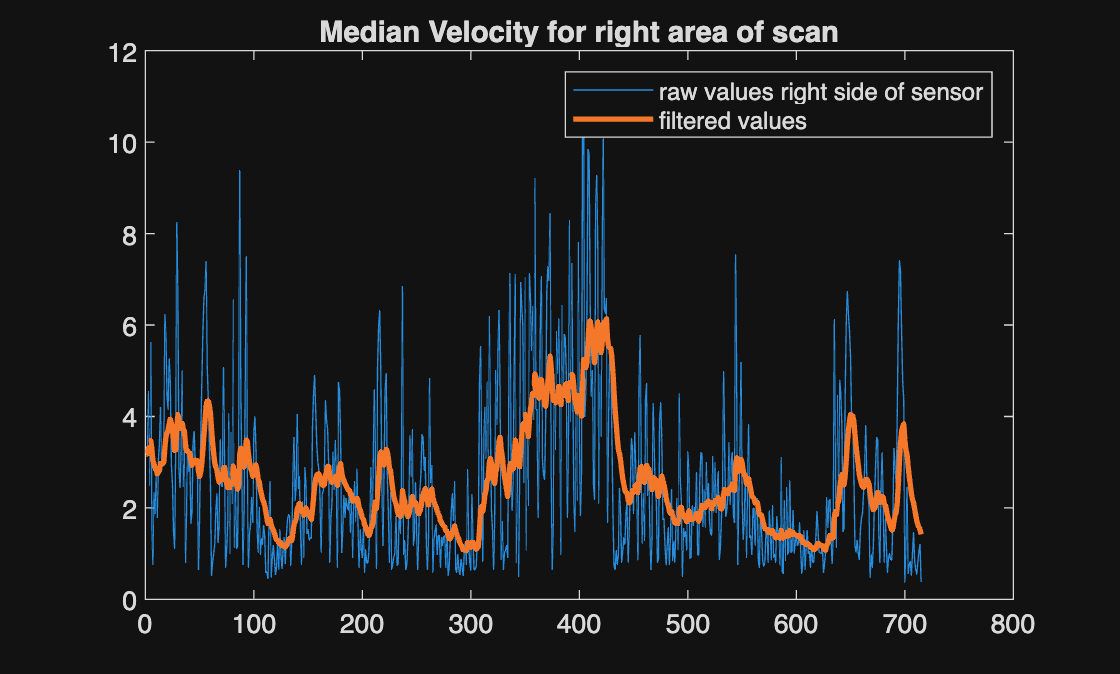

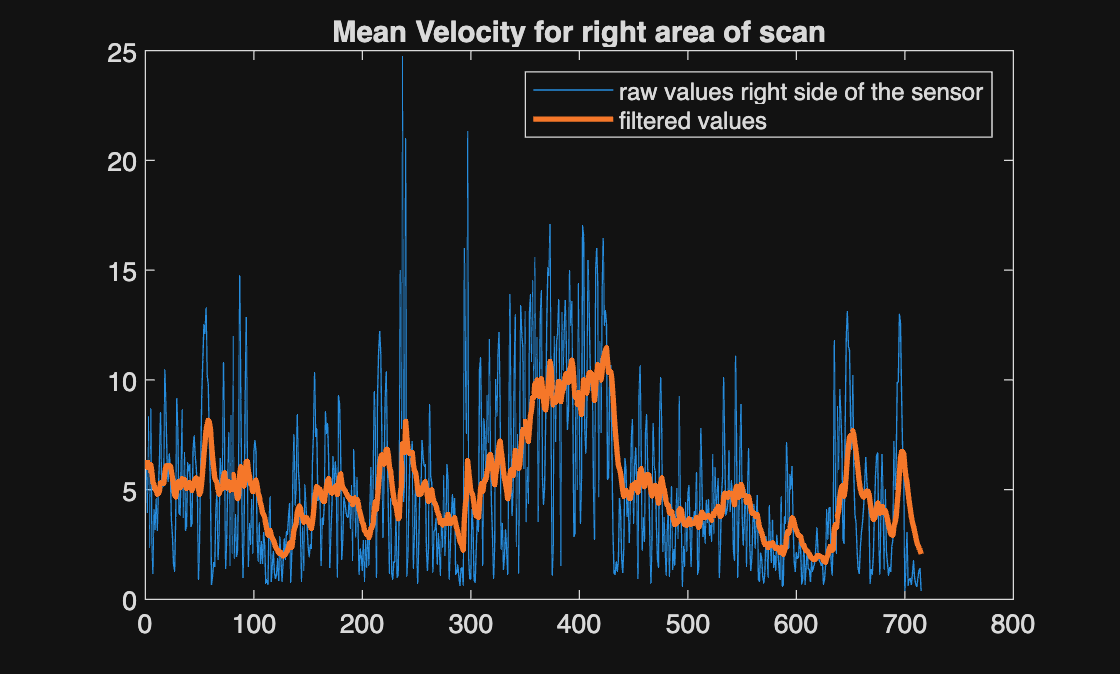

clc; clear; close all;

% Measurements: 
% ================================================== %

% change suffix from 1 to 5 to get different data files 

filepath_r_scan = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_scan_test_street_1.csv';
filepath_xy_scan = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_scan_xy_test_street_1.csv';
filepath_vx_vy = '/Users/madmel/Desktop/Bachelor/Data/25052026/25052026_velocities_x_y_test_street_1.csv';

% ================================================== %
 
% filepath_r_scan = '/Users/madmel/Desktop/Bachelor/Data/06062026/06062026_scan_test_3.csv';
% filepath_xy_scan = '/Users/madmel/Desktop/Bachelor/Data/06062026/06062026_scan_xy_test_3.csv';
% filepath_vx_vy = '/Users/madmel/Desktop/Bachelor/Data/06062026/06062026_velocities_x_y_test_3.csv';

% ================================================== %

% set the scenario: 

handleOvertaking = true; 
handleTailgating = ~handleOvertaking; 

% ================================================== %

% ===== for triming long measurements uncomment the function below ===== %

% trimLidarData(filepath_xy_scan , filepath_r_scan, filepath_vx_vy, 2880, 3400)

% ================================================== %

% ===== load data ===== %

[t_r_, r_all_, t_xy_, x_all_, y_all_, t_velocity, vx_all, vy_all, v] = loadData(filepath_xy_scan, filepath_r_scan, filepath_vx_vy);

% ===== keep only the values with proper velocity ( vel < 20 m/s and vel > 0 m/s) ===== % 

scanPointNumbers = 421; % files come with 421 points now, earlier measurements contained the full scan (811 points per scan)
[x_filtered, y_filtered, vx_filtered, vy_filtered, v_filtered, r_filtered]= filterAllValuesWithProperVelocities(x_all_, y_all_, vx_all, vy_all, v, r_all_, scanPointNumbers);

% ===== define critical area for both scenarios ===== %  

[x_points_in_critical_area, y_points_in_critical_area, x_sensor_back, y_sensor_back] = ExtractPointsInCriticalArea(x_filtered, y_filtered); 

% ===== velocities and egovelocity ===== %

[v_mean, v_median, point_index_median_velocities] = computeMeanMedianVelocity(v_filtered, r_filtered, scanPointNumbers);
[alphafiltered_median, alphafiltered_mean] = alphaFilter(v_median(:,1), v_mean(:,1)); % alpha filter to estimate the ego velocity

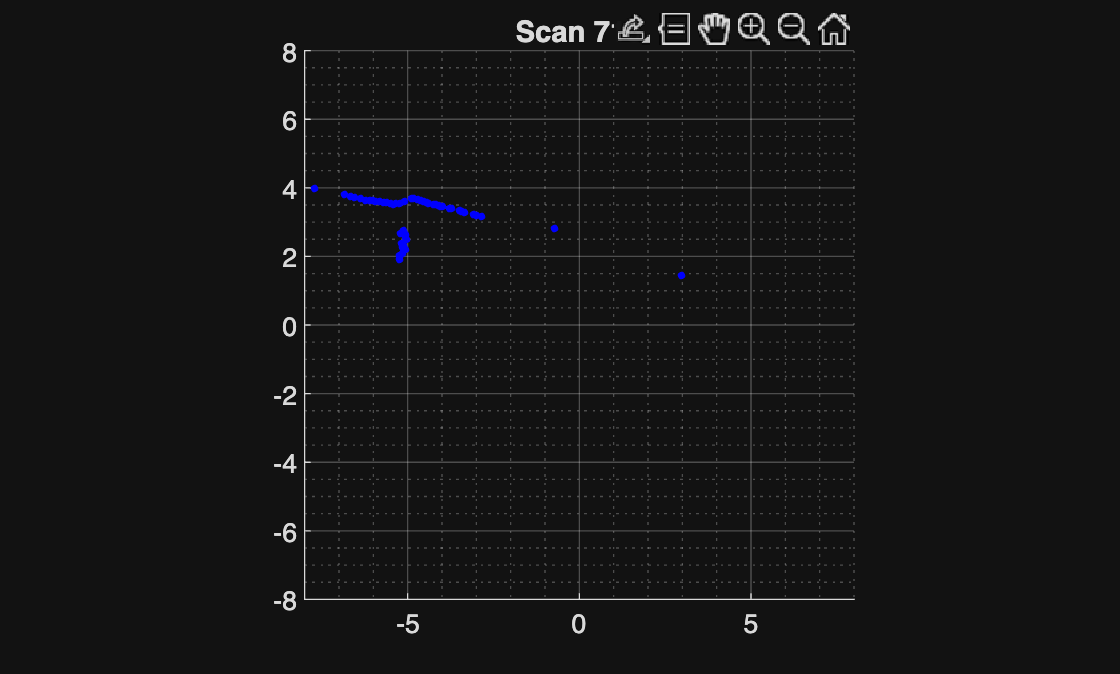

    
% ================================================== %

if handleOvertaking
    
    % ===== segmentation ===== % 
    
    segments_side = findSegments(x_points_in_critical_area, y_points_in_critical_area);

    % ===== clustering ===== %
    
    clusters_side = mergeSegmentsToClustersPerScan(segments_side);
    
    % ===== tracking ===== %
    
    clusters_side_with_id = trackClustersBetweenScans(clusters_side);
    
    % ===== classification and direction of movement ===== %
    
    object_side_properties = classifyClusters(clusters_side_with_id);  % objects: id, direction: object.approaching (true/false)
    
    % ===== detection of potential dangerous situations ===== %
    
    dangerousClustersSide = detectDangerousObjectSide(clusters_side_with_id, object_side_properties, alphafiltered_mean); 

    % ===== final plot ===== %
    
    plotObjects(x_filtered, y_filtered, clusters_side_with_id, object_side_properties, dangerousClustersSide); 

else 
    
    % ===== segmentation ===== % 
    
    segments_back = findSegments(x_sensor_back, y_sensor_back);
       
    % ===== clustering ===== % 
    
    clusters_back = mergeSegmentsToClustersPerScan(segments_back);

    % ===== tracking ===== % 

    clusters_back_with_id = trackClustersBetweenScans(clusters_back);

    % ===== classification ===== % 

    object_back_properties = classifyClusters(clusters_back_with_id);

    % ===== danger detection ===== % 

    dangerousClustersBack = detectDangerousObjectBack(clusters_back_with_id, object_back_properties, alphafiltered_mean);

    % ===== final plot ===== % 

    plotObjects(x_filtered, y_filtered, clusters_back_with_id, object_back_properties); 
    
end 


% ================================================== %
